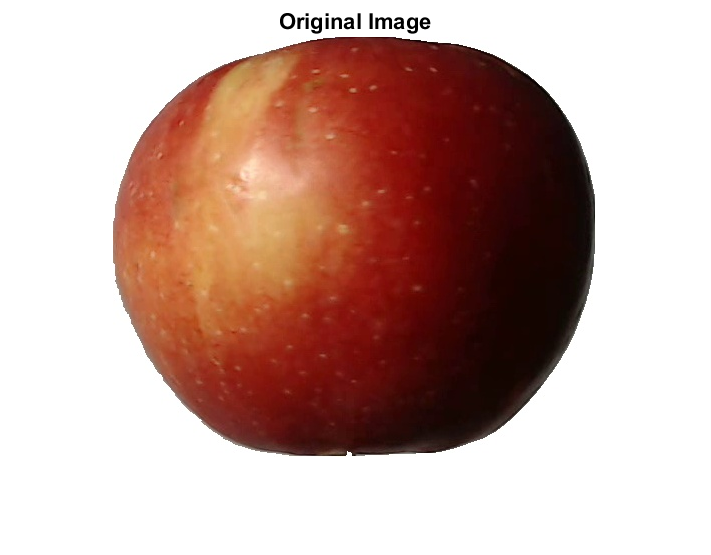

% Load the image
image = imread("C:\Users\HP\Videos\r0_6.jpg"); % Replace with your image file
imshow(image);
title('Original Image');

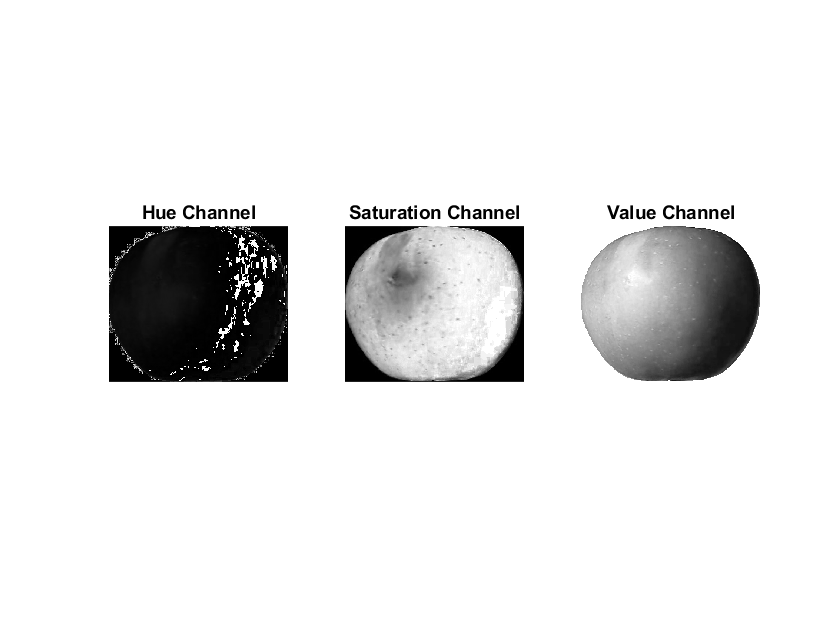


% Convert to HSV color space
hsvImage = rgb2hsv(image);

% Extract Hue, Saturation, and Value channels
hueChannel = hsvImage(:, :, 1);
saturationChannel = hsvImage(:, :, 2);
valueChannel = hsvImage(:, :, 3);

% Display the HSV channels
figure;
subplot(1, 3, 1), imshow(hueChannel), title('Hue Channel');
subplot(1, 3, 2), imshow(saturationChannel), title('Saturation Channel');
subplot(1, 3, 3), imshow(valueChannel), title('Value Channel');

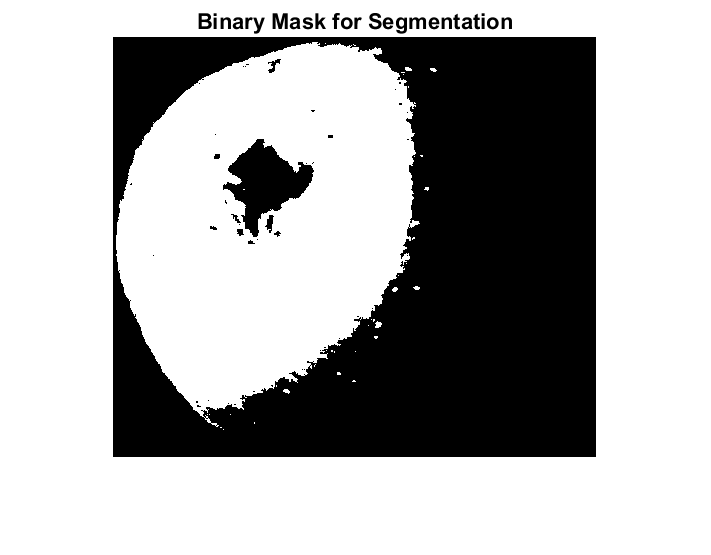


% Thresholding to isolate the food item (depends on food type)
binaryMask = saturationChannel > 0.5 & valueChannel > 0.5; % Adjust thresholds based on the image
figure;
imshow(binaryMask);
title('Binary Mask for Segmentation');

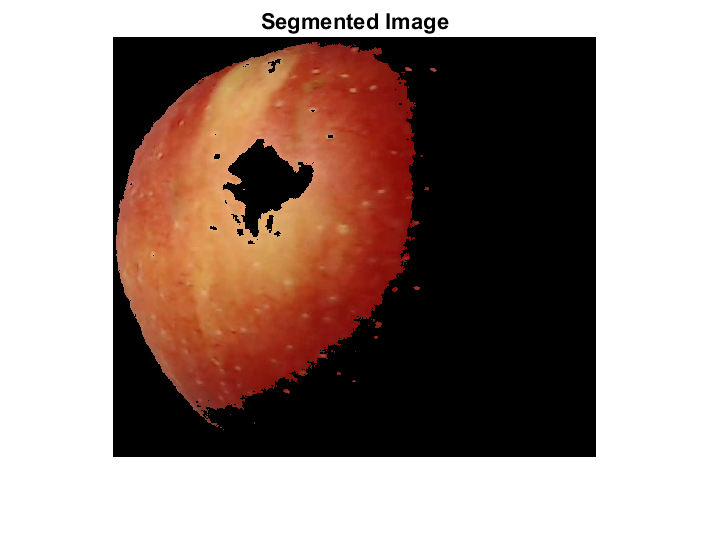


% Apply mask to the original image
segmentedImage = bsxfun(@times, image, cast(binaryMask, 'like', image));
figure;
imshow(segmentedImage);
title('Segmented Image');


% Analyze freshness using mean Hue
meanHue = mean(hueChannel(binaryMask));
disp(['Mean Hue: ', num2str(meanHue)]);

Mean Hue: 0.045197



% Determine freshness and rating
if meanHue > 0.1 && meanHue < 0.3
    freshness = 'Fresh';
    rating = 7 + (0.3 - meanHue) * 10; % Map to 7-10 range
elseif meanHue >= 0.3 && meanHue < 0.6
    freshness = 'Moderately Fresh';
    rating = 4 + (0.6 - meanHue) * 10 / 3; % Map to 4-7 range
else
    freshness = 'Not Fresh';
    rating = max(0, 4 - meanHue * 10); % Map to 0-4 range
end

% Display the results
disp(['The food is ', freshness, '.']);

The food is Not Fresh.


disp(['Freshness Rating (0 to 10): ', num2str(round(rating, 1))]);

Freshness Rating (0 to 10): 3.5



% Save the results to an Excel file
resultTable = table(meanHue, string(freshness), round(rating, 1), ...
    'VariableNames', {'MeanHue', 'Freshness', 'Rating'});
outputFileName = "C:\Users\dhari\OneDrive\Desktop\result.xlsx"; % File name to save the results
writetable(resultTable, outputFileName);

Unable to save the workbook to file 'C:\Users\dhari\OneDrive\Desktop\result.xlsx'. Check that write permissions are available, there is sufficient disk space, and the file can be written to or created.


disp(['Results saved to ', outputFileName]);